%%
clc
clear all
close all

%% Obtendo a planta
[a,z,p1,p2,p3,p4] = getvaluesT1(20102977);

s = tf('s');
G = (a*(s+z))/((s+p1)*(s+p2)*(s+p3)*(s+p4))


G =
 
             124.8 s + 1.098e04
  ----------------------------------------
  s^4 + 52 s^3 + 767.8 s^2 + 2472 s + 2196
 
Continuous-time transfer function.
Model Properties



% Para utilizar a variavel no simulink
[num, den] = tfdata(G, 'v');

%% Polos e Zeros
% Avaliar Estabilidade

[z, gain] = zero(G);
p = pole(G);

z, p, gain

z = -88

p =   -26.0000
  -22.0000
   -2.4000
   -1.6000


gain = 124.8000


% Sistema estável, todos os polos no SPE


## Esboçar o Diagrama de Bode e Gerar no MATLAB

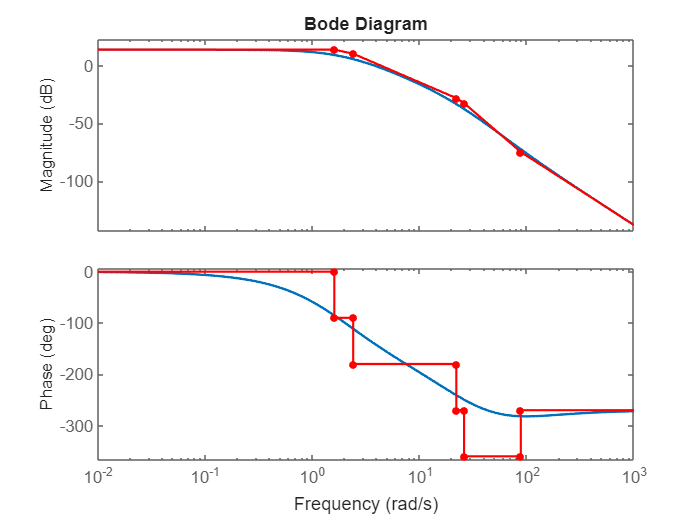


figure(1)
asymp(G)
grid on

## Resposta ao Degrau Unitário em Malha Aberta (MATLAB/Simulink)

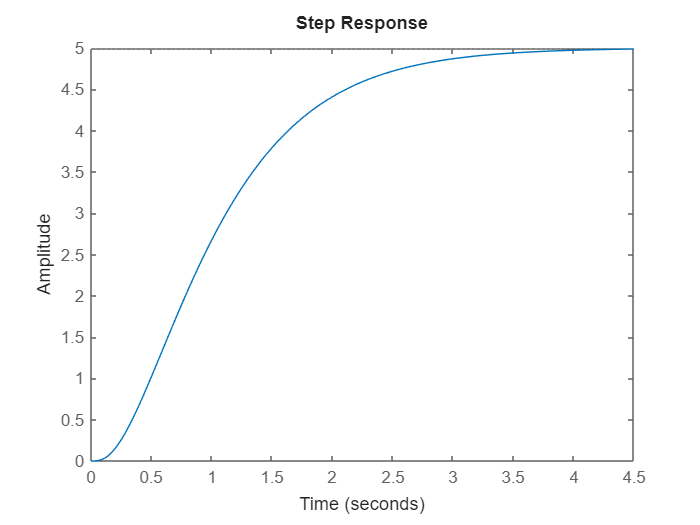

figure(2);
step(G);

## Resposta para sinais senoidais

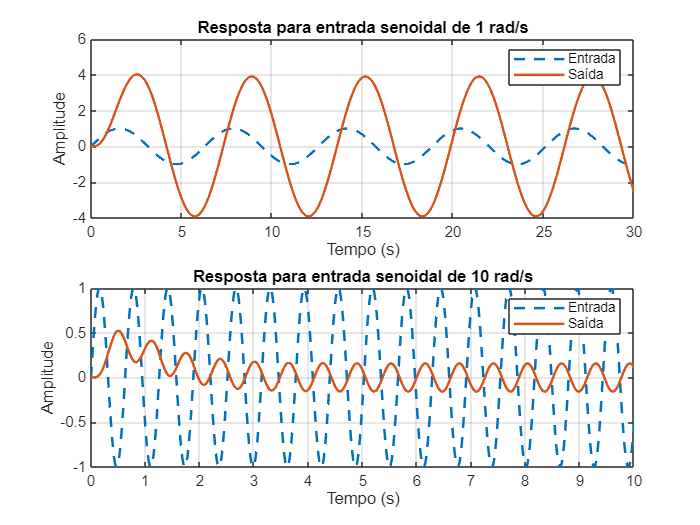


% Amplitude unitária e frequencias de 1 rad/s e 10 rad/s
% Observar alteração de amplitude e fase na resposta
% Ver se o resultado esta de acordo com o Diagrama de Bode

t1 = 0:0.01:30;
i1 = sin(1*t1);
t2 = 0:0.01:10;
i2 = sin(10*t2);

Y1 = lsim(G, i1, t1);
Y2 = lsim(G, i2, t2);

figure(3);
subplot(2,1,1);
plot(t1, i1, '--', t1, Y1, 'LineWidth', 1.5);
title('Resposta para entrada senoidal de 1 rad/s');
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('Entrada', 'Saída');
grid on;

subplot(2,1,2);
plot(t2, i2, '--', t2, Y2, 'LineWidth', 1.5);
title('Resposta para entrada senoidal de 10 rad/s');
xlabel('Tempo (s)');
ylabel('Amplitude');
legend('Entrada','Saída');
grid on;


% Para amplitude: 10^(Magn[dB]/20)
% Para fase: análise de deslocamento eixo X


## Etapa 2:

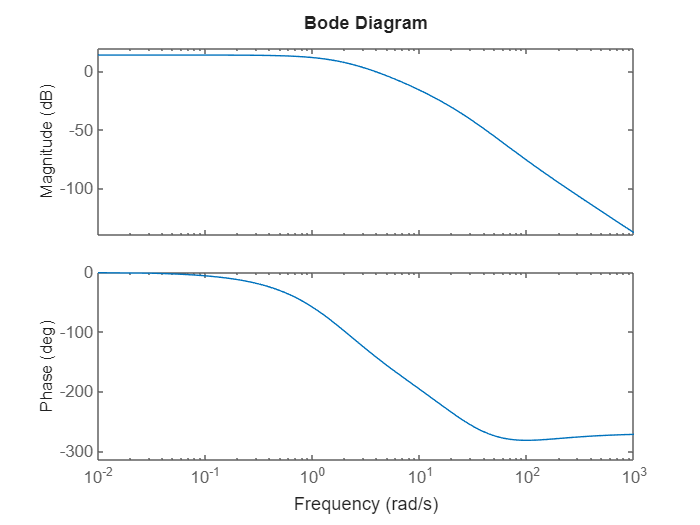


% Margens de Ganho e Fase do Sistema
% Prever se o Gmf com K=1 terá estabilidade

figure(4)
bode(G)

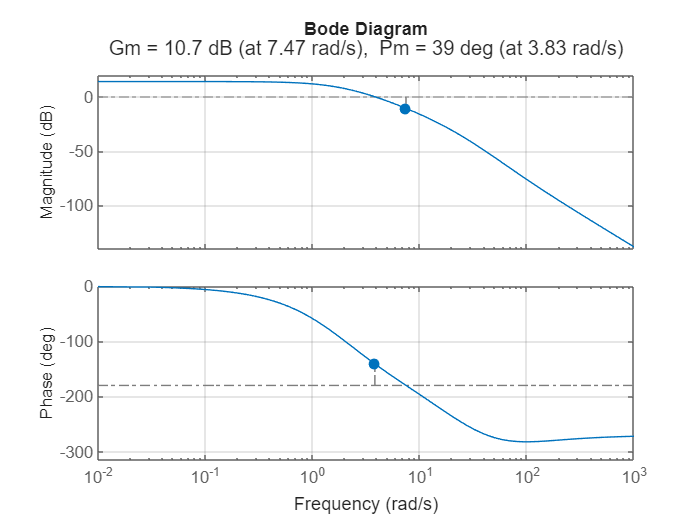

% Medindo margem de fase e ganho
figure(5)
margin(G)
grid on

% Margem de Ganho = 10.7, Margem de Fase = 39
% Sistema Estável pois MG > 0 e MF > 0

Kmax = 10^(10.7/20)

Kmax = 3.4277

## A partir do diagrama de bode determinar Kp


% Qual o erro perante um degrau unitario

Kp = 10^(14/20);
ep = 1/(1+Kp)

ep = 0.1663

## MATLAB/Simulink obter resposta ao degrau da Gmf

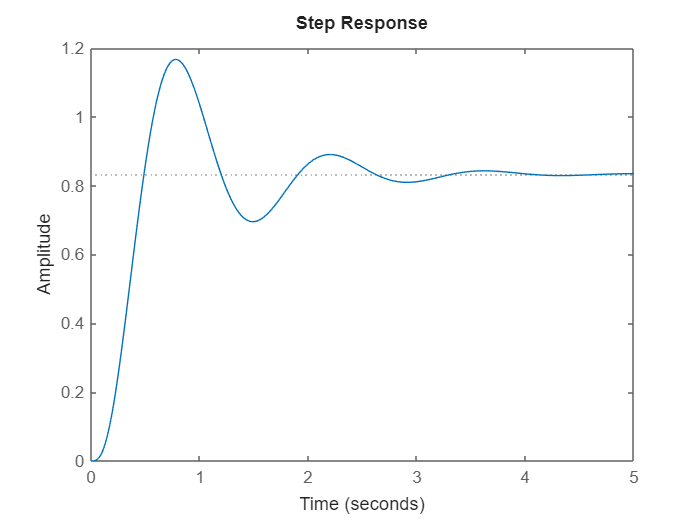


% Testar K=1 e K=Kmax

K = 1;
L = K*G;
Gmf = L / (1+L);

figure(6)
step(Gmf)

[GM, PM, wcg, wcp] = margin(G);

 % Plotar diagrama de Bode com margens
 figure;
 margin(G);
 grid on;

 K1 = 1

K1 = 1

 Kmax = GM

Kmax = 3.4141

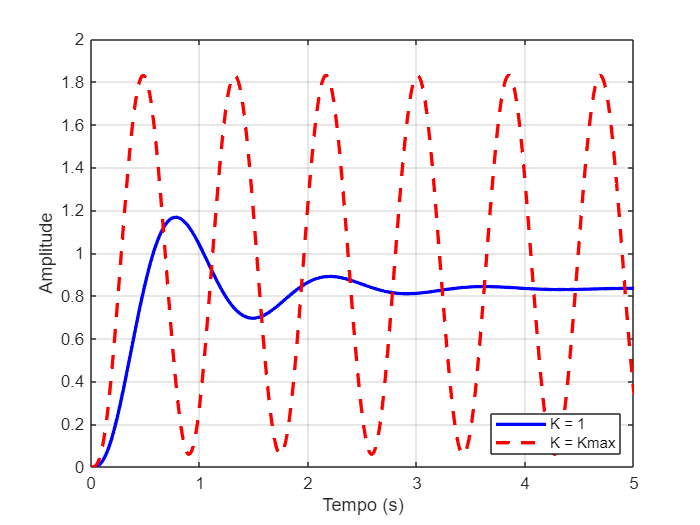

 Gmf1 = feedback(K1 * G, 1);

 Gmf_max = feedback(Kmax * G, 1);
 
 t = 0:0.01:5; 
 [y1, t1] = step(Gmf1, t);     
 [ymax, tmax] = step(Gmf_max, t); 
 
 figure;
 plot(t1, y1, 'b', 'LineWidth', 2); hold on;
 plot(tmax, ymax, 'r--', 'LineWidth', 2);
 grid on;
 xlabel('Tempo (s)');
 ylabel('Amplitude');
 legend('K = 1', 'K = Kmax', 'Location', 'Southeast');

## Etapa 3 Compensação Integral C(s) = K/s

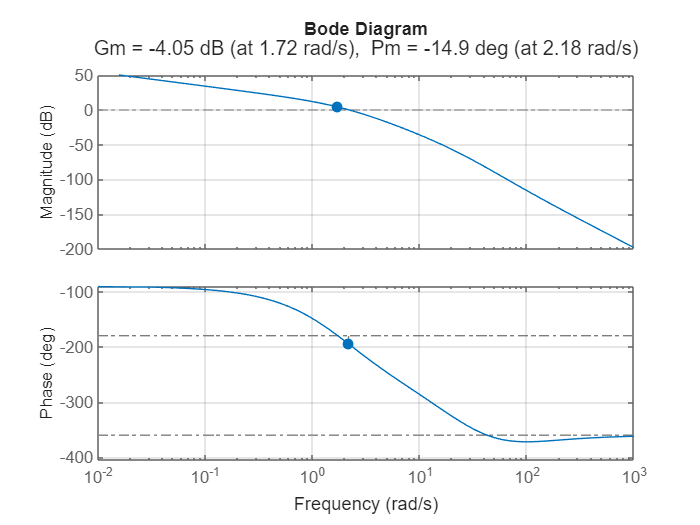


K = 1;
C = K/s;
L_int = C*G;

figure(7)
margin(L_int)
grid on

## Determinar K para Gmf estável e Fase entre 40 e 50


K = 1;
C = K/s;
MF_Original = C*G;

figure(8)
margin(MF_Original)
grid on
hold on

K_new = 10^(-16.1/20)

K_new = 0.1567

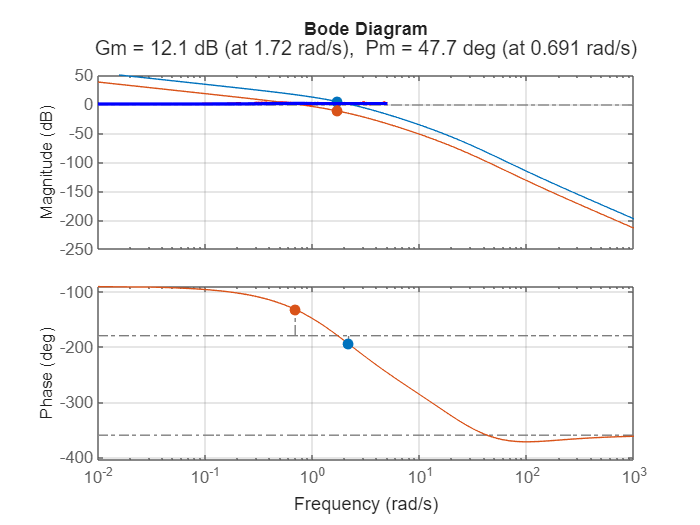

C = K_new/s;
MF_Ajustada = C*G;
margin(MF_Ajustada)

% Kv pelo grafico = 0.691
Kv = 0.691;
ev = 1/Kv

ev = 1.4472

## Definir a estabilidade em Kp e Kv

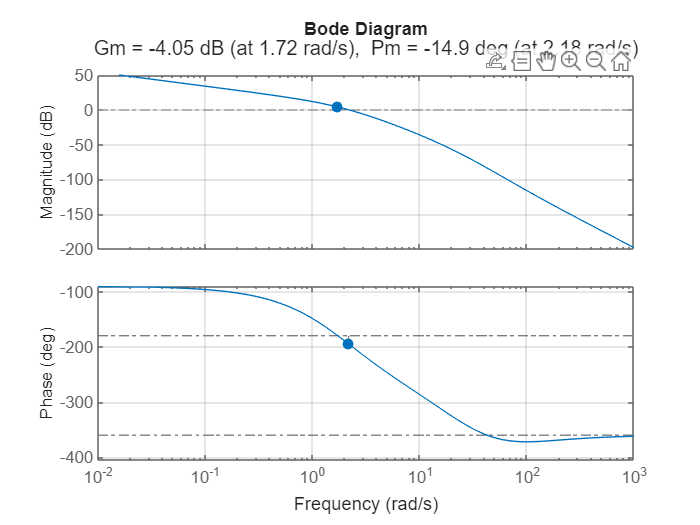

K = 1;
C = K/s;
L = C*G;
figure(9)
margin(L)
grid on
hold on

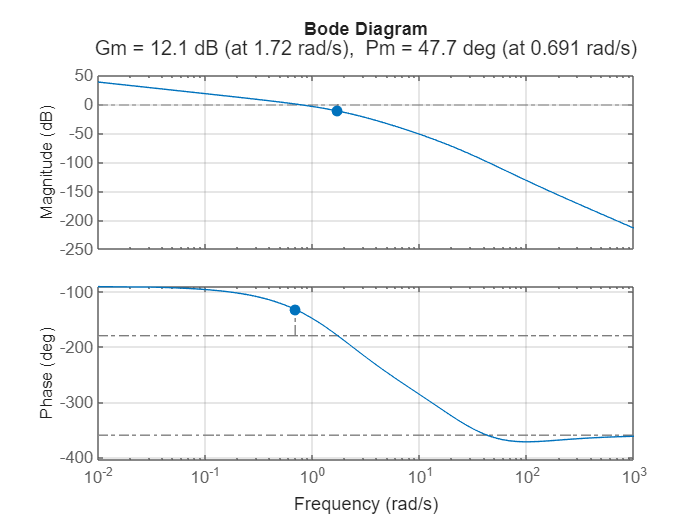

% Com o K para a estabilização de ep e ev
K = 0.1567;
C = K/s;
L = C*G;
figure(10)
margin(L)
grid on
hold on